# MTE 408 ROBOTICS

**Coeded By** : Waleed El-Badry

**Date** : August 2022

In this script, we will find the forward kineamtics of the Spherical Robot (RRP) configiration without using any toolbox. You may follow the same steps to find the forward kinematics from the base frame to the end effector frame.

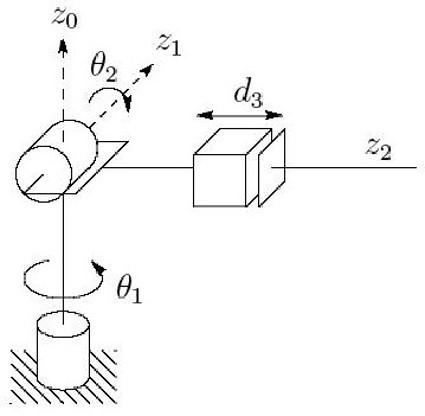

Next, we will define the **robot parameters**:


$$\theta_1 \;,\theta_2 \;,a_1 \;,a_2 \;,a_3 \;,d_3$$


% Robot parameters as symbols
syms th1 th2 d3 a1 a2 a3

Once parameters were defined , we may commence the homogeneous transformation derivation as in the section

### Frame 0 to Frame 1 Homogenous Transformation

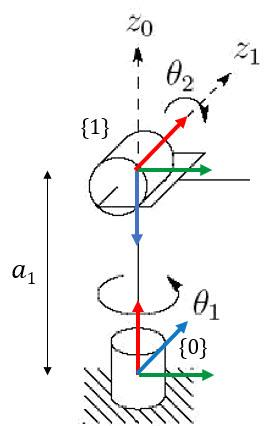


$$R_{z\;} =\left\lbrack \begin{array}{ccc}
{c\theta }_1  & -s\theta_1  & 0\\
s\theta_1  & c\theta_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack ,\;R_1^0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\left(-\frac{\pi }{2}\right) & -s\left(-\frac{\pi }{2}\right)\\
0 & s\left(-\frac{\pi }{2}\right) & c\left(-\frac{\pi }{2}\right)
\end{array}\right\rbrack \;,t_1^0 =\left\lbrack \begin{array}{c}
0\\
0\\
a_1 
\end{array}\right\rbrack$$


% Joint Rotation matrix
Rz = [cos(th1) -sin(th1) 0 ; sin(th1) cos(th1) 0; 0 0 1]

$$Rz = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{1}\right) & 0\\ \sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Frame rotation matrix
R_0_1 = [1 0 0 ; 0 fix(cos(-pi/2)) -fix(sin(-pi/2)) ; 0 fix(sin(-pi/2)) fix(cos(-pi/2))]

R_0_1 =      1     0     0
     0     0     1
     0    -1     0


% Frame translation vector
t_0_1 = [0 ; 0 ; a1]

$$t\_0\_1 = \left(\begin{array}{c} 0\\ 0\\ a_{1} \end{array}\right)$$

% Combined rotation matrix
R_c_0_1 = Rz * R_0_1

$$R\_c\_0\_1 = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\right) & 0 & -\sin\left({\mathrm{th}}_{1}\right)\\ \sin\left({\mathrm{th}}_{1}\right) & 0 & \cos\left({\mathrm{th}}_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

H_0_1 = [R_c_0_1(1,:) t_0_1(1) ; R_c_0_1(2,:) t_0_1(2) ; R_c_0_1(3,:) t_0_1(3) ; 0 0 0 1]

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & 0 & -\sin\left({\mathrm{th}}_{1}\right) & 0\\ \sin\left({\mathrm{th}}_{1}\right) & 0 & \cos\left({\mathrm{th}}_{1}\right) & 0\\ 0 & -1 & 0 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Frame 1 to Frame 2 Homogenous Transformation

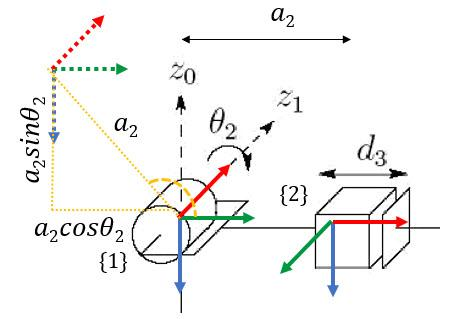


$$R_{z\;} =\left\lbrack \begin{array}{ccc}
{c\theta }_2  & -s\theta_2  & 0\\
s\theta_2  & c\theta_2  & 0\\
0 & 0 & 1
\end{array}\right\rbrack ,\;R_2^1 =\left\lbrack \begin{array}{ccc}
c\left(\frac{\pi }{2}\right) & 0 & s\left(\frac{\pi }{2}\right)\\
0 & 1 & 0\\
-s\left(\frac{\pi }{2}\right) & 0 & c\left(\frac{\pi }{2}\right)
\end{array}\right\rbrack \;,t_1^0 =\left\lbrack \begin{array}{c}
a_2 {c\theta }_2 \\
{-a}_2 {s\theta }_2 \\
0
\end{array}\right\rbrack$$


% Joint Rotation matrix
Rz = [cos(th2) -sin(th2) 0 ; sin(th2) cos(th2) 0; 0 0 1]

$$Rz = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{2}\right) & -\sin\left({\mathrm{th}}_{2}\right) & 0\\ \sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Frame rotation matrix
R_1_2 = [fix(cos(pi/2)) 0 fix(sin(pi/2)) ; 0 1 0 ; fix(-sin(pi/2)) 0 fix(cos(pi/2))]

R_1_2 =      0     0     1
     0     1     0
    -1     0     0


% Frame translation vector
t_1_2 = [a2*cos(th2) ; -a2*sin(th2) ; 0]

$$t\_1\_2 = \left(\begin{array}{c} a_{2}\,\cos\left({\mathrm{th}}_{2}\right)\\ -a_{2}\,\sin\left({\mathrm{th}}_{2}\right)\\ 0 \end{array}\right)$$

% Combined rotation matrix
R_c_1_2 = Rz * R_1_2

$$R\_c\_1\_2 = \left(\begin{array}{ccc} 0 & -\sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right)\\ 0 & \cos\left({\mathrm{th}}_{2}\right) & \sin\left({\mathrm{th}}_{2}\right)\\ -1 & 0 & 0 \end{array}\right)$$

H_1_2 = [R_c_1_2(1,:) t_1_2(1) ; R_c_1_2(2,:) t_1_2(2) ; R_c_1_2(3,:) t_1_2(3) ; 0 0 0 1]

$$H\_1\_2 = \left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right) & a_{2}\,\cos\left({\mathrm{th}}_{2}\right)\\ 0 & \cos\left({\mathrm{th}}_{2}\right) & \sin\left({\mathrm{th}}_{2}\right) & -a_{2}\,\sin\left({\mathrm{th}}_{2}\right)\\ -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Frame 2 to End Effector Homogenous Transformation

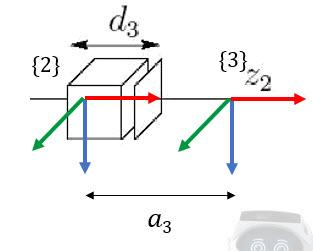


$$R_{z\;} =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack ,\;R_3^2 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \;,t_1^0 =\left\lbrack \begin{array}{c}
0\\
0\\
a_3 +d_3 
\end{array}\right\rbrack$$


% Joint Rotation matrix
Rz = [1 0 0 ; 0 1 0 ; 0 0 1]

Rz =      1     0     0
     0     1     0
     0     0     1


% Frame rotation matrix
R_2_3 = [1 0 0 ; 0 1 0 ; 0 0 1]

R_2_3 =      1     0     0
     0     1     0
     0     0     1


% Frame translation vector
t_2_3 = [0 ; 0 ; a3 + d3]

$$t\_2\_3 = \left(\begin{array}{c} 0\\ 0\\ a_{3}+d_{3} \end{array}\right)$$

% Combined rotation matrix
R_c_2_3 = Rz * R_2_3

R_c_2_3 =      1     0     0
     0     1     0
     0     0     1


H_2_3 = [R_c_2_3(1,:) t_2_3(1) ; R_c_2_3(2,:) t_2_3(2) ; R_c_2_3(3,:) t_2_3(3) ; 0 0 0 1]

$$H\_2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & a_{3}+d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Homogeneous Transformation Matrix from Frame 0 To End Effector

H_0_3 = H_0_1 * H_1_2 * H_2_3

$$H\_0\_3 = \left(\begin{array}{cccc} \sin\left({\mathrm{th}}_{1}\right) & -\cos\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right)\,\left(a_{3}+d_{3}\right)+a_{2}\,\cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right)\\ -\cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right)\,\sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{2}\right)\,\sin\left({\mathrm{th}}_{1}\right)\,\left(a_{3}+d_{3}\right)+a_{2}\,\cos\left({\mathrm{th}}_{2}\right)\,\sin\left({\mathrm{th}}_{1}\right)\\ 0 & -\cos\left({\mathrm{th}}_{2}\right) & -\sin\left({\mathrm{th}}_{2}\right) & a_{1}-\sin\left({\mathrm{th}}_{2}\right)\,\left(a_{3}+d_{3}\right)+a_{2}\,\sin\left({\mathrm{th}}_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Example

For the above spherical robot, given :


$$\theta_1 \;={30}^o ,\theta_2 \;={45}^o \;,a_1 \;\;=\;0\ldotp 25\;m\;,a_2 \;=\;0\ldotp 3\;m\;,a_3 \;=\;0\ldotp 12\;m\;,d_3 =0\ldotp 2\;m$$


Find the end effector final position using the derived forward kineamtics

**Answer**

% Robot Joint parameters
th1  = deg2rad(30);
th2 = deg2rad(45);
d3 = 0.2;
a1 = 0.25;
a2 = 0.3;
a3 = 0.12;

Getting the configuration

Rz = [cos(th1) -sin(th1) 0 ; sin(th1) cos(th1) 0; 0 0 1];
R_0_1 = [1 0 0 ; 0 fix(cos(-pi/2)) -fix(sin(-pi/2)) ; 0 fix(sin(-pi/2)) fix(cos(-pi/2))];
t_0_1 = [0 ; 0 ; a1];
R_c_0_1 = Rz * R_0_1;
H_0_1 = [R_c_0_1(1,:) t_0_1(1) ; R_c_0_1(2,:) t_0_1(2) ; R_c_0_1(3,:) t_0_1(3) ; 0 0 0 1];

Rz = [cos(th2) -sin(th2) 0 ; sin(th2) cos(th2) 0; 0 0 1];
R_1_2 = [fix(cos(pi/2)) 0 fix(sin(pi/2)) ; 0 1 0 ; fix(-sin(pi/2)) 0 fix(cos(pi/2))];
t_1_2 = [a2*cos(th2) ; -a2*sin(th2) ; 0];
R_c_1_2 = Rz * R_1_2;
H_1_2 = [R_c_1_2(1,:) t_1_2(1) ; R_c_1_2(2,:) t_1_2(2) ; R_c_1_2(3,:) t_1_2(3) ; 0 0 0 1];

Rz = [1 0 0 ; 0 1 0 ; 0 0 1];
R_2_3 = [1 0 0 ; 0 1 0 ; 0 0 1];
t_2_3 = [0 ; 0 ; a3 + d3];
R_c_2_3 = Rz * R_2_3;
H_2_3 = [R_c_2_3(1,:) t_2_3(1) ; R_c_2_3(2,:) t_2_3(2) ; R_c_2_3(3,:) t_2_3(3) ; 0 0 0 1];

H_0_3 = H_0_1 * H_1_2 * H_2_3

H_0_3 =     0.5000   -0.6124    0.6124    0.3797
   -0.8660   -0.3536    0.3536    0.2192
         0   -0.7071   -0.7071    0.2359
         0         0         0    1.0000


% End Effector position with respect to Base Frame
EEp = [H_0_3(1:3,4)]

EEp =     0.3797
    0.2192
    0.2359
